# Comparision of Vehicle Dynamic Model 1 with Real Vehicle

To simulate the vehicle dynamic characteristic as much as possible, we need to compare our model in Simulink with real vehicle datas. This file shows how to compare vehicle dynamic model 1 with Volvo V70 and the comparision result. 

## Prepare and Run Simulation

We first clear the work space and load measured data of the Volvo V70. The  "System identification" package is required.

load(fullfile(matlabroot, 'toolbox', 'ident', 'iddemos', 'data', 'vehicledata'));

The data of the Volvo V70 is stored in "u3" and "y3". For more detailed information you can check data and text.

data

data = '{y1, u1}: simulation wiht high stiffness; {y2, u2}: simulation with low stiffness; {y3, u3}: measured data'

text

text = 'y [longitudinal velocity, lateral acc, yaw rate] and u [slip front left, slip front right, slip rear left, slip rear right, steering angle] are the data for the bicycle vehicle model'

To use the data of the Volvo V70 in simulink model, we need to change the data into a time series array.

Ts=0.1;%sample time
t=0:Ts:250;%simulation end time 250s
WhlAngF.time=t;
WhlAngF.signals.values=[u3(:,5),u3(:,5)];
xdotin.time=t;
xdotin.signals.values=y3(:,1);

After input data is defined, we run the Simulink model to check the outputs.

load_system('first_option');
set_param('first_option','StopTime','250');
sim('first_option');

## Result Comparision

Lateral acceleration of the vehicle dynamic model and Volvo V70.

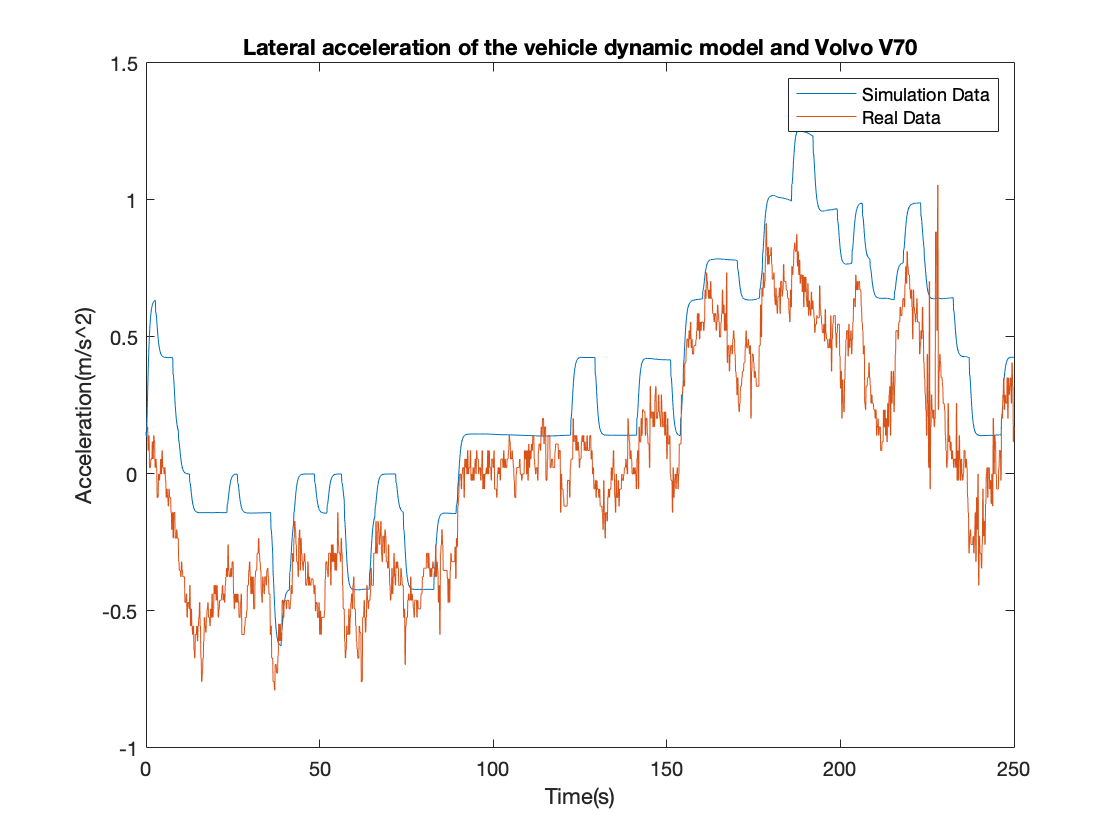

plot(t,ans.lateral_acc.Data);
hold on 
plot(t,y3(:,2));
legend('Simulation Data','Real Data');
xlabel('Time(s)');
ylabel('Acceleration(m/s^2)');
hold off
title('Lateral acceleration of the vehicle dynamic model and Volvo V70');

Yaw rate of the vehicle dynamic model and Volvo V70.

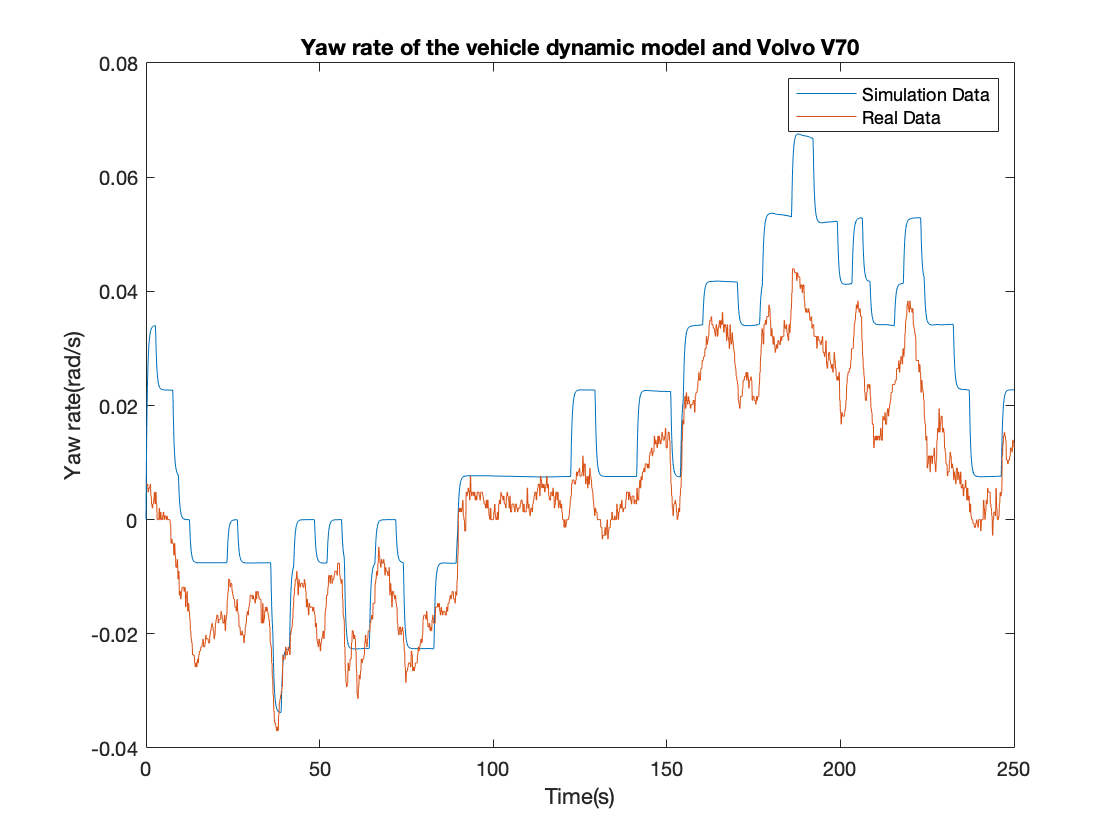

plot(t,ans.yaw_rate.Data);
hold on 
plot(t,y3(:,3));
legend('Simulation Data','Real Data');
xlabel('Time(s)');
ylabel('Yaw rate(rad/s)');
hold off
title('Yaw rate of the vehicle dynamic model and Volvo V70');